# Phys 434 Lab 3

## Natalie Shen

### Collaborators: Francesca Bennet, Taylor Prewitt

#### Hours:

clear all; close all; clc

### Problem 1

#### A)

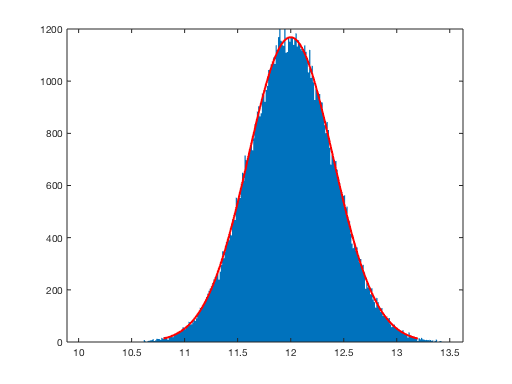

r = normrnd(12,.4,[1,100000]);
histfit(r);

bd = [10., 10.3, 2.1, 0, 0, 15.6, 22.3, 12.7]

bd =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


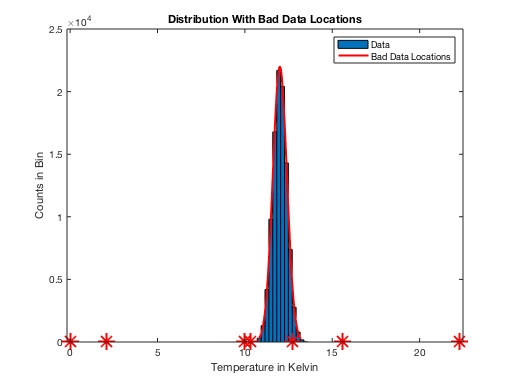

b = [10., 10.3, 2.1, 0, 15.6, 22.3, 12.7];
bq = [1,1,1,2,1,1,1];
A = [r b];
histfit(A,100);
hold on
plot(b, bq, 'r*', 'LineWidth', 2, 'MarkerSize', 15);
title("Distribution With Bad Data Locations");xlabel("Temperature in Kelvin");ylabel("Counts in Bin")
legend('show',"Data","Bad Data Locations")
hold off

#### B)

Statistical Question:

Which data points stand outside of the normal standard deviation of 0.4?

Will the removal of said data points influence the data as a whole?

Would attempting to filter out the bad data points also result in the removal of the good data points?

#### C)

I'm going to convert all the data points to percentages based on the distribution. I will then be comparing the probabilities to see whether they are within a specific range. If so then this data is then "kept", if not then it is discarded. I will be running thorugh both the normal data and the "bad data".

#### D)

%first run, limit: sigma1
%limits
mu = 12;
sigma = .4;
ll = mu - sigma;
hl = mu + sigma;

%for regular data
g1count = 0;
b1count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b1count = b1count + 1;
    elseif r(z) > hl
        b1count = b1count + 1;
    else
        g1count = g1count + 1;
    end
end

%for bad data
bg1count = 0;
bb1count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb1count = bb1count + 1;
    elseif bd(z) > hl
        bb1count = bb1count + 1;
    else
        bg1count = bg1count + 1;
    end
end


%second run, limit: sigma3
%limits
mu = 12;
sigma = .4;
ll = mu - 3 * sigma;
hl = mu + 3 * sigma;

%for regular data
g2count = 0;
b2count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b2count = b2count + 1;
    elseif r(z) > hl
        b2count = b2count + 1;
    else
        g2count = g2count + 1;
    end
end

%for bad data
bg2count = 0;
bb2count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb2count = bb2count + 1;
    elseif bd(z) > hl
        bb2count = bb2count + 1;
    else
        bg2count = bg2count + 1;
    end
end

%third run, limit: sigma5
%limits
mu = 12;
sigma = .4;
ll = mu - 5 * sigma;
hl = mu + 5 * sigma;

%for regular data
g3count = 0;
b3count = 0;
for z = 1:1:length(r)
    if r(z) < ll
        b3count = b3count + 1;
    elseif r(z) > hl
        b3count = b3count + 1;
    else
        g3count = g3count + 1;
    end
end

%for bad data
bg3count = 0;
bb3count = 0;
for z = 1:1:length(bd)
    if bd(z) < ll
        bb3count = bb3count + 1;
    elseif bd(z) > hl
        bb3count = bb3count + 1;
    else
        bg3count = bg3count + 1;
    end
end

disp("First run results: (Sigma1)")

First run results: (Sigma1)


g1count

g1count = 68131

b1count

b1count = 31869

bg1count

bg1count = 0

bb1count

bb1count = 8


disp("Second run results: (Sigma3)")

Second run results: (Sigma3)


g2count

g2count = 99708

b2count

b2count = 292

bg2count

bg2count = 1

bb2count

bb2count = 7


disp("Third run results: (Sigma5)")

Third run results: (Sigma5)


g3count

g3count = 99999

b3count

b3count = 1

bg3count

bg3count = 3

bb3count

bb3count = 5

Posiive True = Good data kept

Negative True = Good data thrown out (due to limitation)

Positive False = (Bad data kept (due to being within the limitation)

Negative False = (Bad data thrown out)

(Using data from a random run, other run's data may not be exact but they should be similar)

Truth Table:

### B)

The good data that was tossed out decreased more as I increased sigma, which is predictible since earlier sigmas leave out about about 30-40% of data, which is accurate with the findings.

### C)

There will always be mistakes that could occur resulting in bad data being mixed in with the good data. Some are avoidable if you narrow down the limits of where the data is expected to be, in this case narrowing down to anywhere between 3 to 5 ish sigma.

## Problem 2

### 1.

Since the distance traveled is so small that it lies in sigma5 territory, how much distancance (in arcseconds) has the object traveled within that small amount of distance.

#### 2.

distance =  sqrt(x^2 + y^2)

Xlim=-3:0.1:3;
X=normpdf(Xlim,0,1);
Y=normpdf(Xlim,0,1);
D=(X.^2+Y.^2).^.5;
r=raylpdf(D,2);
%prob of sigma 5 is 1 out of 3.5 million
sigma5p=1/(3.5 * 10.^6);
ArcLDis=icdf("rayleigh", 1-sigma5p,1,2)

ArcLDis = 5.4897

plot(Xlim,r);
hold on
plot(ArcLDis,0,'r*', 'LineWidth', 2, 'MarkerSize', 15);

### Problem 3

#### 1.

How much significant data is lost due to the interferance of the moon?

#### 2.

Converting GRB/min to total expected GRB for 8 hours a day for 15 days:

1 GRB/min * (60min / hr) * 8 hrs * 15 days = 7200 total GRB

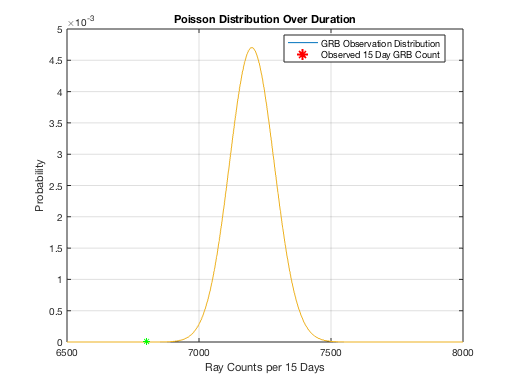

x = 0:8000;
exp = 7200;
p = poisspdf(x,exp);
stairs(x,p);
title('Poisson Distribution Over Duration');ylabel("Probability");xlabel("Ray Counts per 15 Days");
xlim([6500 8000]);
grid on
hold on
x3=6800;
plot(x3,0,"Color","r","Marker","*")
legend('show',"GRB Observation Distribution","Observed 15 Day GRB Count","Location","best")
hold off

#### 3.

As seen in this equation, sigma is squared, so we have to square root the recorded value first before salving for sigma.

sqr=sqrt(7200);
z=normcdf(6800,7200,sqr);
sigma = abs(norminv(z))

sigma = 4.7140

Timestamp: 3 hrs tuesday, 3 hours saturday, 2 hours sunday.